#### Resampling na 100 Gs/s

Korzystaj z plików z kopii zapasowej.

x100 = resample(x,100,10);

#### Korelacja

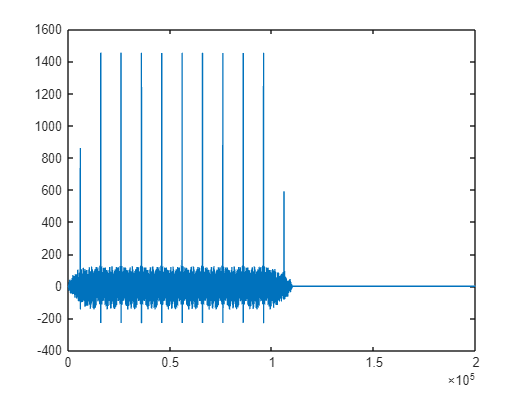

cor = xcorr(x100,gen100);
plot(cor);

#### Przycięcie

fd1 = finddelay(x100,gen100)

fd1 = 34065

gen_cut1 = gen100(fd1:fd1+9999);
new_gen1 = gen100(fd1+10000:end);

fd2 = finddelay(x100, new_gen1)

fd2 = 30001

gen_cut2 = new_gen1(fd2:fd2+9999);
new_gen2 = new_gen1(fd2+10000:end);

fd3 = finddelay(x100,new_gen2)

fd3 = 1

gen_cut3 = new_gen2(fd3:fd3+9999);
new_gen3 = new_gen2(fd3+10000:end);

fd4 = finddelay(x100,new_gen3)

fd4 = 1

Index exceeds the number of array elements. Index must not exceed 5936.

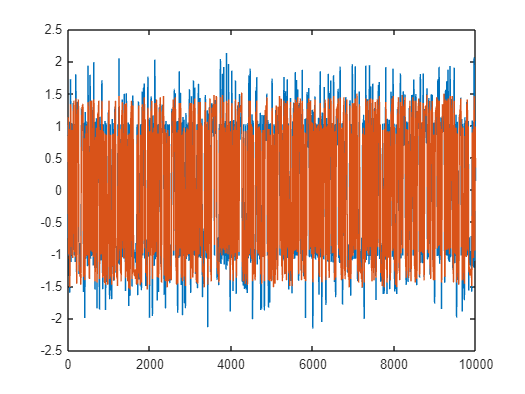

x100=x100./rms(x100);
for i=1:4
    nazwa_zmiennej = ['gen_cut' num2str(i)]; 
    komenda = ['= gen_cut' num2str(i) './rms(gen_cut' num2str(i) ');'];
    eval([nazwa_zmiennej komenda]);
end

figure(1)
plot(x100)
hold on
plot(gen_cut1)
hold off

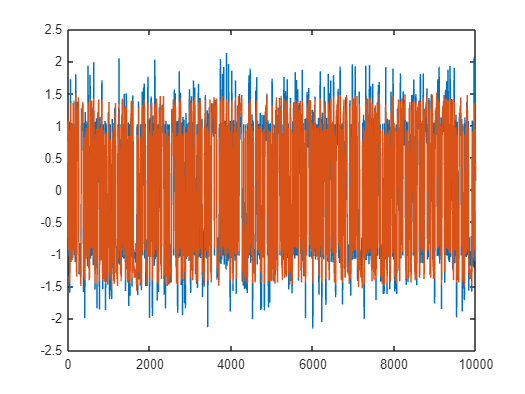

figure(2)
plot(x100)
hold on
plot(gen_cut2)
hold off

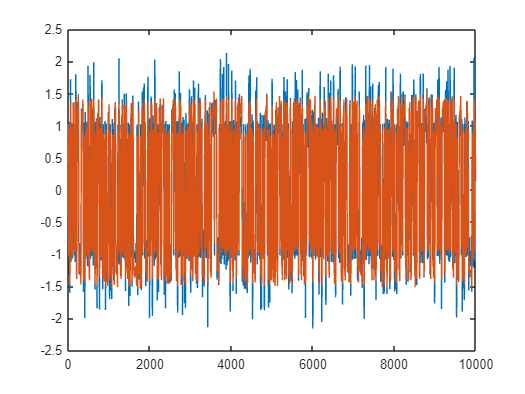

figure(3)
plot(x100)
hold on
plot(gen_cut3)
hold off

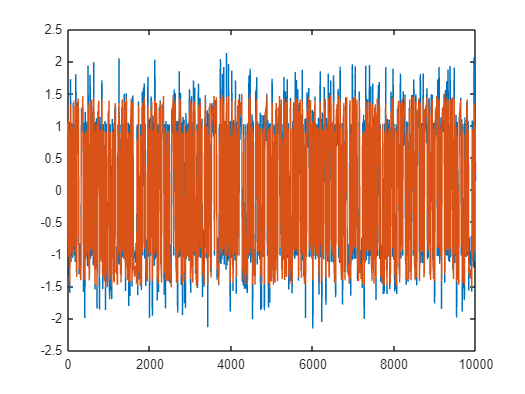

figure(4)
plot(x100)
hold on
plot(gen_cut4)
hold off

#### Zmiana fazy

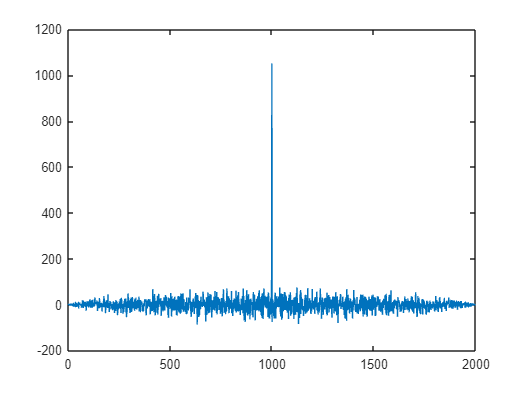

for i=1:4
    nazwa_zmiennej = ['gen_cut_ds' num2str(i)]; 
    komenda = ['= downsample(gen_cut' num2str(i) '(1:end),10);'];
    eval([nazwa_zmiennej komenda]);
end
cor = xcorr(x,gen_cut_ds1);
plot(cor)

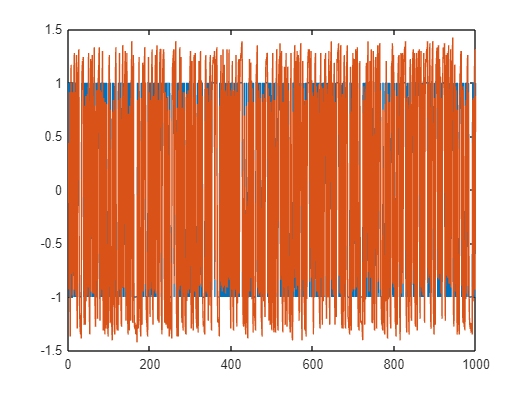

figure(9)
plot(x)
hold on
plot(gen_cut_ds1)
hold off

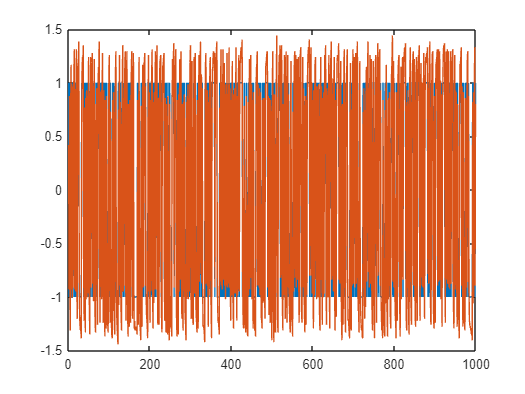

figure(10)
plot(x)
hold on
plot(gen_cut_ds2)
hold off

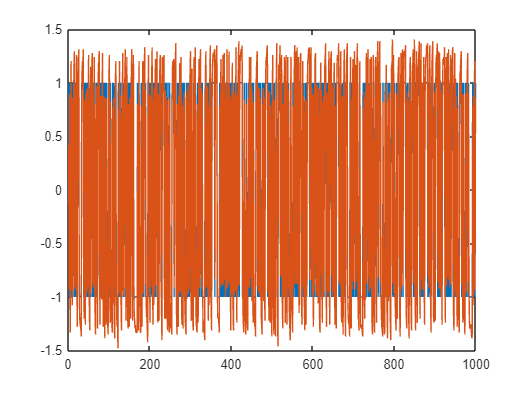

figure(11)
plot(x)
hold on
plot(gen_cut_ds3)
hold off

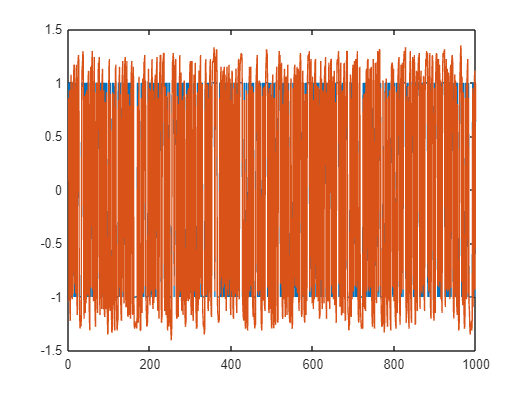

figure(12)
plot(x)
hold on
plot(gen_cut_ds4)
hold off

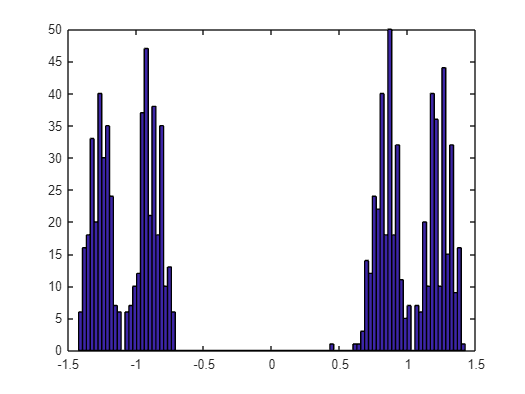

hist(gen_cut_ds1,100)

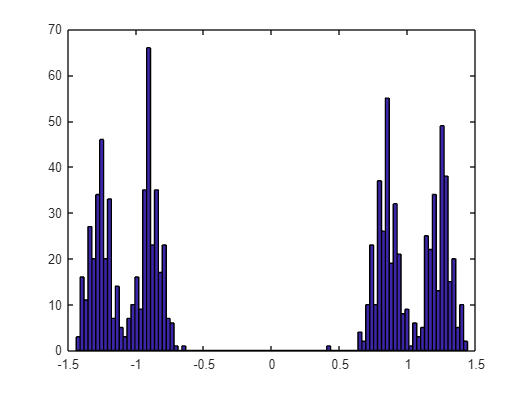

hist(gen_cut_ds2,100)

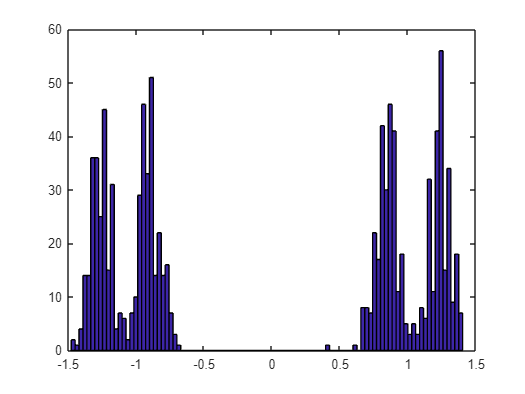

hist(gen_cut_ds3,100)

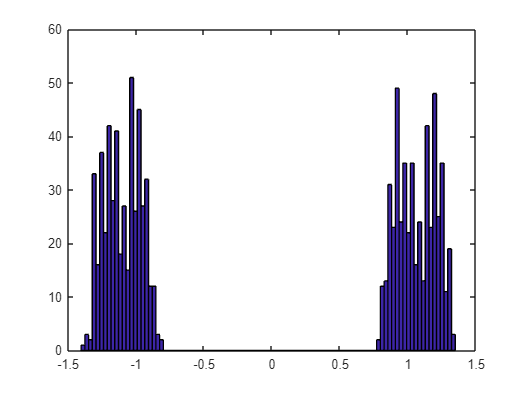

hist(gen_cut_ds4,100)

#### Zamiana na 0 i 1

x_norm = x+1;
x_norm = x_norm/2;
for i=1:8
    nazwa_zmiennej = ['gen_cut_ds_dig' num2str(i)]; 
    komenda = ['= dig(gen_cut_ds' num2str(i) ');'];
    eval([nazwa_zmiennej komenda]);
end

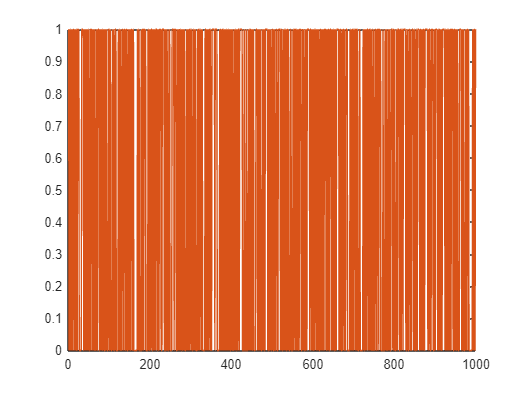

figure(17)
plot(x_norm)
hold on
plot(gen_cut_ds_dig1)
hold off

#### Sprawdzenie

function gen_cut_ds_dig = dig(gen_cut_ds)
    gen_cut_ds_dig = ones(1000,1);
    
    for i=1:length(gen_cut_ds_dig)
        if gen_cut_ds(i,1) < 0
            gen_cut_ds_dig(i,1)=0;
        end
        if gen_cut_ds(i,1) > 0
            gen_cut_ds_dig(i,1)=1;
        end
    end
end